# kg2 - Multi Fish kg

## load data

load("/Volumes/Elements/kg2.mat");
%load("/Users/eric/Documents/MATLAB/kg2backup.mat");

AT HOME

%load("/Users/kathryngallman/Documents/MATLAB/kg2backup.mat");
%save("/Volumes/Elements/kg2.mat", 'kg2');

## save data structure

IN LAB

%save("/Users/eric/Documents/MATLAB/kg2backup.mat", "kg2", '-v7.3');
save("/Volumes/Elements/kg2.mat", 'kg2', '-v7.3');
save("/Volumes/My Book/Gallman/kg2.mat", 'kg2', '-v7.3');

AT HOME

% save("/Users/kathryngallman/Documents/MATLAB/kg2backup.mat", "kg2", '-v7.3');
% save("/Volumes/Elements/kg2.mat", 'kg2', '-v7.3');

# Multiple fish

## reference raw data folder and asign k value

%raw data files live on the MyBook. Thankfully... ugh.
cd("/Volumes/Elements/Gallman/33LD/Multi3LD-Sept-26-2022-B/");
k = 68;

## **2:2 LD**

k = 32           2:2 LD    MultiEigenLL2LDGreyBabes-July-18-2022-A          SHIT DATA

k = 42           2:2 LD    MultiLLto2LD-July-19-2022-B                                  ONLY LOW FREQ FISH

k = 60           2:2 LD    Multi2LD-Aug-24-2022-A                                        HI FREQ FISH DIDN'T TUBE UNTIL END

k = 61           2:2 LD    Multi2LD-Aug-24-2022-B                                        NO DARK DATA FOR LO FREQ FISH %not 

## 3:3 LD

k = 67            3:3 LD    Multi3LD-Sept-26-2022-A

k = 68            3:3 LD    Multi3LD-Sept-26-2022-B

## **4:4 LD**

k = 19           4:4 LD    MultiEigen04-Aug-31-2021-B                                   NOT MUCH DATA - HI FREQ MOSTLY - need to redo... ugh.

k = 21           4:4 LD    MultiEigen4LD-April-26-2022-B                                WHAT JAR?

k = 20           4:4 LD    MultiFrankPinkerton4LD-May-4-2022-B  -                ONLY HI FREQ FISH

k =   72         4:4 LD    ReinMulti4LD-April-26-2022-A ONLY                        HI FREQ FISH - no lo freq dark data- also missing?

k = 22           4:4 LD    ReinMulti4LD-May-4-2022-A                                     MOSTLY HI FREQ FISH

## **5:5 LD** 

k = 23            5:5 LD   Multi5LD-April-13-2022-A                                           MOSTLY LO FREQ FISH

k = 24            5:5 LD   MultiEigen5LD-April-13-2022-B                                  WEIRD AMP THING IN HI FREQ

## **6:6 LD**

k = 25            6:6 LD    Multi6LD-May-29-2022-B                                        

 k = 26           6:6 LD    MultiEigen6LD-May-29-2022-A                                BASICALLY NO LO FISH - FREQ IS SHORTER?

## **8:8 LD**

k = 27            8:8 LD     MultiFrankPInkerton8LD-May-10-2022-B                LA

k = 28            8:8 LD     MultiMoanaUnmultiBgravid8LD-May-17-2022-A    MOSTLY LOW FREQ FISH

k = 29            8:8 LD     Multipremulti8LD-May-17-2022-B                           STILL MULTIMODAL WITH WEIRD AMP IN HIGH FISH

## **10:10 LD**

k = 9            10:10 LD     MultiEigen10-Jan-07-2022-B                                MOSTLY HI FREQ FISH

k = 10          10:10 LD     MultiEigen10-Sept-28-2021-B                                NO LO FISH DARK

k = 30          10:10 LD     MultiEigen10-Sept-24-2021-B                                MOSTLY LOW FREQ

## **12:12 LD**

k = 2           12:12 LD     MultiEigen12-Oct-04-2021-B                                  NO DARK DATA FOR LO FISH  

k = 3           12:12 LD     MultiEigen12-July-13-2021-B                                LO FISH WEIRDNESS

k = 4           12:12 with XXat end    MultiEigen12-June-29-2021-B              MOSTLY HI FISH - MAYBE TRIM TEMP

k = 6           12:12 LD     MultiEigen12-Oct-11-2021-B

*k = 32          12:12 LD    MultiEigen12-Jan-04-2022-B    BARELY ANY DATA -SKIPPED*

*k = 33          12:12 LD    MultiEigen12-Oct-20-2021-B   -                                ACTUALLY 124*

k = 64           12:12 LD    MultiEigen12-Feb-25-2022-B

## **13:13 LD**

k = 33           13:13 LD     MultiEigen13-March-31-2022-B                    NOT BAD

k = 56            13:13 LD    MultiNewEnrico13LD-Aug-10-2022-B            ONLY HI FREQ FISH

k = 57            13:13 LD    MultiSnow13LD-Aug-10-2022-A     NO TUBE 1 DATA - MOSTLY HI FREQ FISH

## **16:16 LD**

k = 62          16:16 LD     MultiEigen16Ld-July-31-2022-B                    NO HI FISH DATA

k = 63          16:16 LD      MultiOldNew16LD-Aug-2-2022-A                NO HI FISH DATA

## **20:20 LD**

k = 34           20:20 LD     MultiEigen20-Jan-17-2022-B

k = 59                                MultiLL20LD-Aug-18-2022-B kinda noisy        LL ONLY REALLY NOT WORTH IT

k = 60            frequency track successful but all amp values -0.1        MultinewoldLL20LD-Aug-18-2022

## **24:24 LD**

k = 73,74           24:24 LD     MultiEigen24-Dec-05-2021-B                            DONE

k = 13            24:24 LD    MultiEigen24-Sept-3-2021-B                            STARTS WITH LIGHT

## **48:48 LD**

k = 14            48:48 LD    MultiEigen48-Dec-17-2021-B  (low freq fish has no dark data)

k = 15            48:48LDtemp     MultiEigen48-July-19-2021-B     (hi freq fish data is crap - ignore) - not completely perfect - pain in my ass      

                       max-20 min-3

                        will need to redo obw amp to account for weird midpoints - freqidxs should be correct - just not the midpoint NOT MUCH LO FISH

k = 16            48:48LDtemp    MultiEigen48LDtemp-Jan-28-2022-B         LIGHTTIMES ARE WEIRD

k = 17            48:48LDtemp     MultiEigen48temp-Feb-14-2022-B

k = 65            48:48 LD            Multi48LD-Sept-04-2022-A -new

k = 75           48:48 LD            Multi48LD-Sept-01-2022-B

## **124 LD**

k =  1          124 LD     MultiEigen12-Oct-20-2021-B

k = 5           124 LD     MultiEigen124-Nov-04-2021-B

k = 37         124 LD     MultiEigen124-Nov-18-2021-B

### **DARK PULSES**

## **5L:1D (6Ldpulse)**

k =  11         5L:1D     MultiEigen6Ldpulse-March-22-2022-B

## **1L:5D (6Dlpulse)**

k =  38        1L:5D     Multi6Dlpulse-April-9-2022-A

k = 39         1L:5D     MultiEigen6Dlpulse-April-9-2022-B

## **11L:1D (12Ldpulse)**

k =  40        11L:1D     MultiEigen12Ldpulse-March-15-2022-B

## **1L:11D (12Dlpulse)**

k =  41        1L:11D    MultiEigen12Dlpulse-April-18-2022-B

### **XXLD and temp**

## **LLtemp**

k = 18        LL 12temp    MultiEigen12-Feb-25-2022-B    NEED TO TRIM

k = 42        LL 12temp    MultiEigenLL12temp-May-25-2022-A        actually zero data

k = 43        LL 12temp    MultiEigenLLtemp-May-23-2022-A        also nope

k = 44        LL 12temp    MultiLLtemp-May-25-2022-B    TRIM END OR RETRACK

**temp**

**XX**

k = 45        XXtemp        MultiEigenXX-Aug-23-2021-B

k = 46        XXtemp        MultiEigenXX-Aug-10-2021-B    

k = 47        XXtemp        MultiEigenXX-July-30-2021-B

**12LD**

k = 56           12:12 LD     MultiEigen12-July-13-2021-B

**DD**

k = 48        DD        MultiDD-July-26-2022-B

k = 49        DD        MultiEigenDDGreyBabes-July-26-2022-A     SHIT TUBING = not worth it

#### LL

k = 50        LL    MultiEigen4LD-April-26-2022-B

k = 51        LL    ReinMulti4LD-April-26-2022-A

k = 52        LL    MultiFrankPinkerton4LD-May-4-2022-B

k = 53        LL    MultiEigenLL2LDGreyBabes-July-18-2022-A

k = 54        LL    MultiLLto2LD-July-19-2022-B   

k = 55           4:4 LD    ReinMulti4LD-May-4-2022-A        NO LL DATA

%raw data files live on the MyBook. Thankfully... ugh.
% kg2(k).s = separationAnxiety('Eigen*');
% kg2(k).fish = KatieFishFinder(kg2(k).s, 20);

## multi plotter

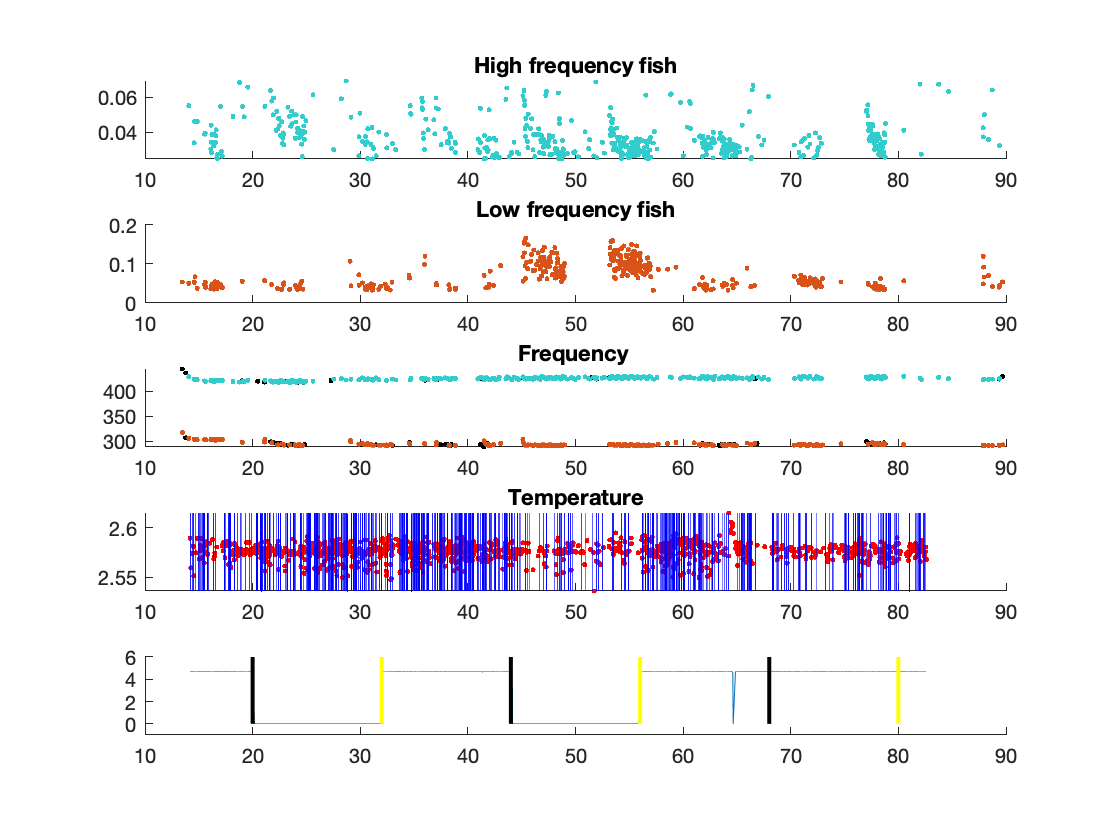

k_multiplotter(kg2(k));

#### Remove outliers

kg2(k).idx = KatieMultiRemover(kg2(k).fish);

#### Label

kg2(k).info = KatieMultiLabeler(kg2(k));

Unrecognized function or variable 'kg2'.

kg2(k).info.luz = k_manuallightlabeler(kg2(k));

lidx = find(abs(hkg(k).info.luz)< 207);
hkg(k).info.luz = hkg(k).info.luz(lidx);